# Hough Transform Line Detection

Reading the image

image = imread('test1.jpg');

Converting the image to gray

image_gray  = rgb2gray(image);

Edge Detection

image_edge = edge(image_gray,'canny');

Hough Transform

[H,theta,rho] = hough(image_edge,'RhoResolution',0.5,'Theta',-90:0.5:89);

Display the original image and the Hough matrix.

subplot(2,1,1);
imshow(image);
title('test1.jpg');
subplot(2,1,2);
imshow(imadjust(rescale(H)),'XData',theta,'YData',rho,'InitialMagnification','fit');
title('Hough transform of test1.jpg');
xlabel('\theta'), ylabel('\rho');
axis on, axis normal, hold on;

Finding peaks in the Hough transform of the image.

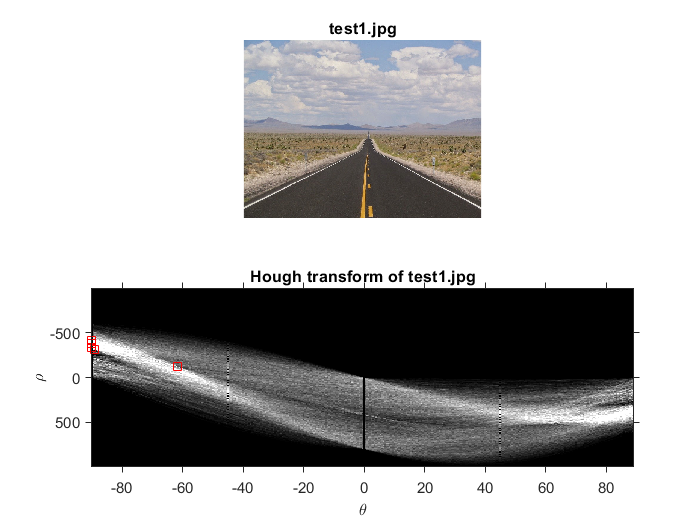

P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
x = theta(P(:,2)); y = rho(P(:,1));
plot(x,y,'s','color','red');

Finding lines and plotting them.

line = houghlines(image_edge,theta,rho,P,'FillGap',5,'MinLength',7);
figure, imshow(image_gray), hold on
max_len = 0;
for k = 1:length(line)
   xy = [line(k).point1; line(k).point2];
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green');

   % Plot beginnings and ends of line
   plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
   plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');

   % Determine the endpoints of the longest line segment
   len = norm(line(k).point1 - line(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end

Highlight the longest line segment by coloring it cyan.

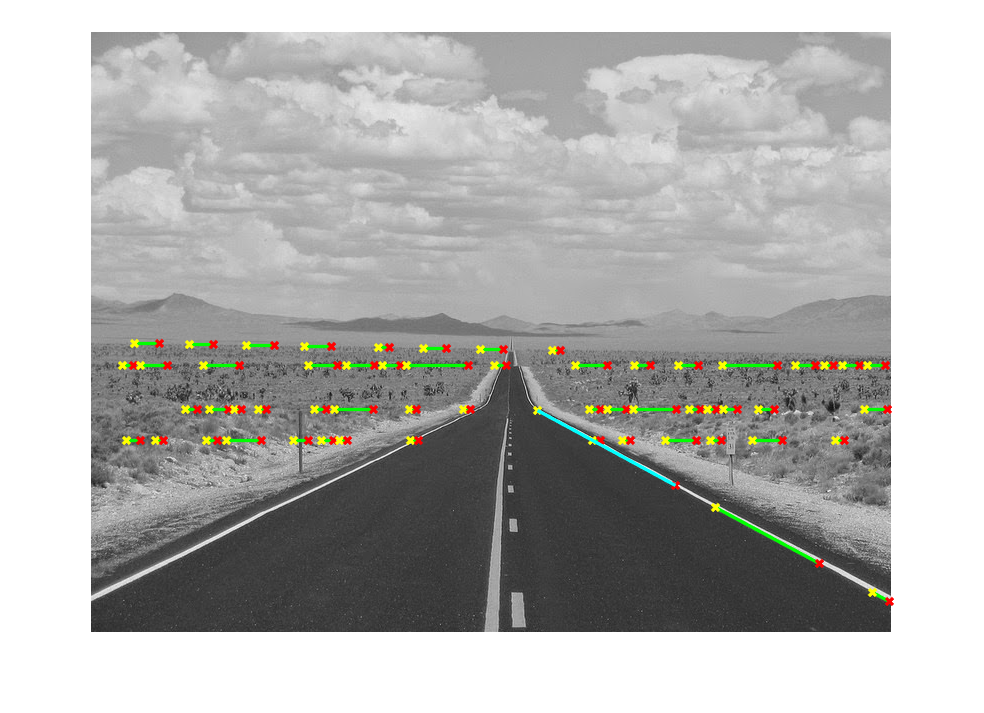

plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');